# Report prestazioni per il sistema Connect Kit

Questo è il secondo file di corredo al primo che mostrava i fondamenti della soluzione adottata. Questo articolo esegue un'analisi dei dati raccolti, nell'ipotesi (da verificare) che siano sufficienti e significativi. Seguirà l'interpretazione degli stessi.

## Caricamento dati 

`Attenzione a cambiare il path in caso di nuova esecuzione!!`

load logfilenosqm.mat
idx=find(logfilenosqm.Transfer>100);
logfilenosqm.Transfer(idx)=logfilenosqm.Transfer(idx)/1000;
idx=find(logfilenosqm.Jitter>100);
logfilenosqm.Jitter(idx)=logfilenosqm.Jitter(idx)/1000;
idx=find(logfilenosqm.Bandwidth>100);
logfilenosqm.Bandwidth(idx)=logfilenosqm.Bandwidth(idx)/1000;

## Test di esattezza delle misurazioni eseguite con il software

Nel caso ideale di ritardo di elaborazione nullo e perdita di info trascurabile è possibile considerare come lineare la relazione che lega larghezza di banda con quantità di dati trasferiti.

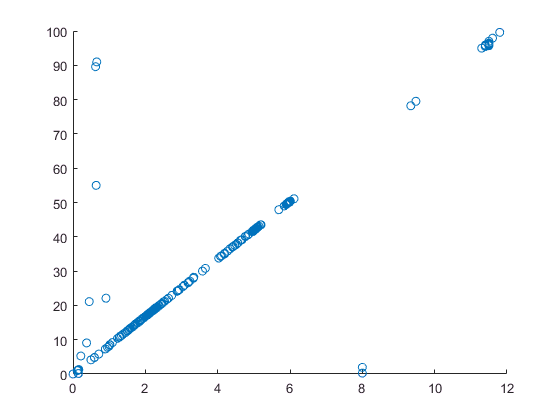

scatter(logfilenosqm.Transfer,logfilenosqm.Bandwidth)

## Presentazione dati raccolti

summary(logfilenosqm)


Variables:

    Transfer: 261×1 double

        Values:

            Min            0        
            Median         2.43     
            Max            11.8     
            NumMissing     1        

    Bandwidth: 261×1 double

        Values:

            Min            0         
            Median         20.8      
            Max            99.6      
            NumMissing     1         

    Jitter: 261×1 double

        Values:

            Min            0.10041 
            Median         1.458   
            Max            85.873  
            NumMissing     1       

    Drop_prob: 261×1 double

        Values:

            Min            0         
            Median         56        
            Max            96        
            NumMissing     1         



Si mostrano i dati riguardanti latenza e larghezza di banda associata raccolti nell'arco 12 minuti.

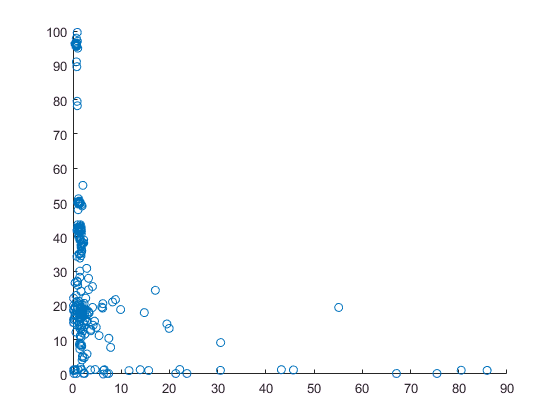

scatter(logfilenosqm.Jitter,logfilenosqm.Bandwidth)

Non è possibile clacolare media e altri parametri statistici poichè mancano valori determinanti, il grafico è "bucato" soprattutto nella zona di jitter > 20 ms. Questo valore non tiene contro del ritardo "di gruppo" cioè del ritard che tutti i pacchetti subiscono, ma semplicemente di variazioni "anomale" nelle latenze registrate nelle varie misurazioni di flusso.Questo comportamento è in accordo con le linee guida in quanto un jitter anomalo è indice di una rete che ha un comportamento "isterico" in quanto non risce a processare il tutto in modo lineare.

In queso sub-set dei dati si riesce  a vedere come intanto si riesce a valutare i parametri statistici dei dati, quindi non ho "buchi" il che vuol dire che le misurazioni sono andate a buon fine. La macchietta di dati che abbiamo in cima è il regime normale di operazion senza alcun tipo di filmato. Estraggo adesso il sottoinsieme dei dati che sono con jitter < 10 ms; questo è un valore signifcativo che nella fattispecie è circa 2.5 volte la latenza, un valore abbastanza ampio di jitter. In generale approssimando il traffico con una distribuzione normale si il 99% dei valori devono essere inclusi in un range $\pm {3\sigma }^2$ in realtà si vede che:

idx=find(logfilenosqm.Jitter<10);
sub_jitter=logfilenosqm.Jitter(idx);
sub_bandwidth=logfilenosqm.Bandwidth(idx);
CreateGraph(sub_jitter,sub_bandwidth)

ciò non è vero in quanto si ha una certa dispersione fra i valori con sistema scarico e carico.

## Presentazione ed analisi del sistema con sqm

load logfilesqmripulitosqm.mat
idx=find(logfileconsqmripulito.Transfer>100);
logfileconsqmripulito.Transfer(idx)=logfileconsqmripulito.Transfer(idx)/1000;
idx=find(logfileconsqmripulito.Jitter>100);
logfileconsqmripulito.Jitter(idx)=logfileconsqmripulito.Jitter(idx)/1000;
idx=find(logfileconsqmripulito.Bandwidth>100);
logfileconsqmripulito.Bandwidth(idx)=logfileconsqmripulito.Bandwidth(idx)/1000;

Osserviamo che abbiamo valori molto più dipsersi rispetto al caso precedente pur normalizzando i valori di 3 ordini di grandezza il jitter otteniamo comunque un comportamento che all'apparenza sembra peggio in quanto usando nuovamente come metrica il jitter nel trasporto del flusso da punto a punto nella rete, vediamo come si abbia un andamento a dente di sega che tende ad "aumentare" in modulo, fino ad esplodere dopo un'ora di proiezione dle filmato, in un jitter che sfora ${10}^3 \text{ }\mathrm{ms}$, Lo stesso andamento lo si osserva anche normalizzando il tutto come detto di 3 ordini di grandezza, il che è segno di una condizione patologica generalizabile a tutti i ttipi di flusso massicci TCP/UDP (definiamo flussi massicci come quei flussi che tendono ad avere la caratteristica *high-throughput, *cioè flussi che sono invariati da latenze a singhiozzo nel percorso e/o picchi di ritardi di propagazione.

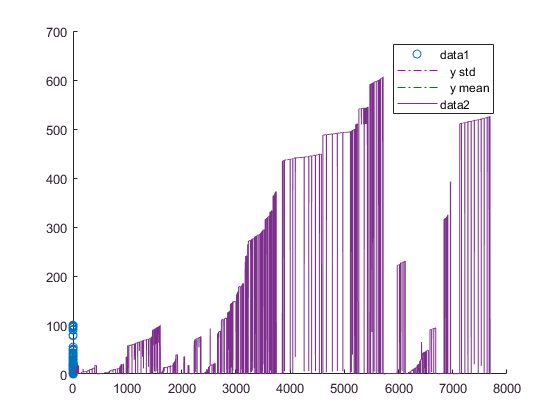

plot(logfileconsqmripulito.Jitter)

Dal grafico della larghezza di banda disponibile vediamo che ci sono molti "buchi"